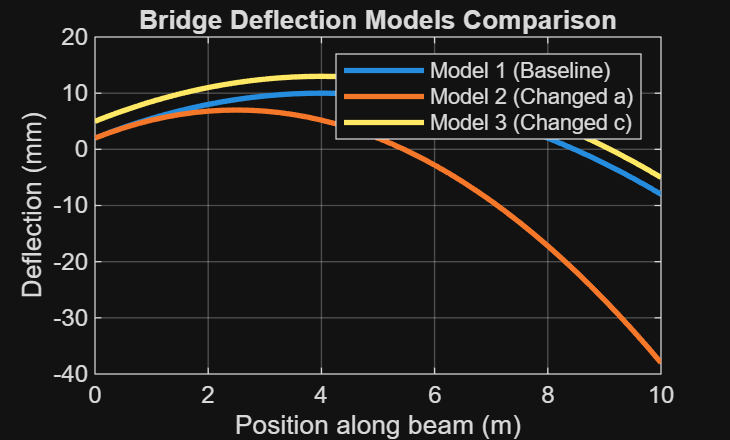

% Zulaikha Khan 
% ES 115 Engineering Computer Applications 
% Module 2 Project: Bridge Deflection Model Comparison 
% Instructor: Lynroy Grant 
% April 2026 
 
clear; clc; close all; 
 
% Define x values (position along beam) 
x = 0:0.25:10; 
 
% ---------------------------- 
% Model 1 (Baseline) 
a1 = -0.5; 
b1 = 4; 
c1 = 2; 
 
d1 = a1*x.^2 + b1*x + c1; 
 
% ---------------------------- 
% Model 2 (change a only) 
a2 = -0.8; % steeper curve 
b2 = b1; 
c2 = c1; 
 
d2 = a2*x.^2 + b2*x + c2; 
 
% ---------------------------- 
% Model 3 (change c only) 
a3 = a1; 
b3 = b1; 
c3 = 5; % vertical shift 
 
d3 = a3*x.^2 + b3*x + c3; 
 
% ---------------------------- 
% Plot all models 
figure; 
plot(x, d1, 'LineWidth', 2); hold on; 
plot(x, d2, 'LineWidth', 2); 
plot(x, d3, 'LineWidth', 2); 
 
title('Bridge Deflection Models Comparison'); 
xlabel('Position along beam (m)'); 
ylabel('Deflection (mm)'); 
legend('Model 1 (Baseline)', 'Model 2 (Changed a)', 'Model 3 (Changed c)'); 
grid on; 

 
% ---------------------------- 
% Find maximum deflection for each model 
 
[max1, idx1] = max(d1); 
x1 = x(idx1); 
 
[max2, idx2] = max(d2); 
x2 = x(idx2); 
 
[max3, idx3] = max(d3); 
x3 = x(idx3); 
 
% Display results 
fprintf('Model 1 max deflection: %.2f mm at x = %.2f m\n', max1, x1); 

Model 1 max deflection: 10.00 mm at x = 4.00 m


fprintf('Model 2 max deflection: %.2f mm at x = %.2f m\n', max2, x2); 

Model 2 max deflection: 7.00 mm at x = 2.50 m


fprintf('Model 3 max deflection: %.2f mm at x = %.2f m\n', max3, x3); 

Model 3 max deflection: 13.00 mm at x = 4.00 m
